% ROSBag file processing
close all
clear

bag = rosbag('bag/controller_test/controller_follow_test_4.bag');
topics = bag.AvailableTopics;

rabbit = select(bag,'Topic','april_cube/rabbit');
boat0 = select(bag,'Topic','/robot0/sandwich_0/sensors/p3d');
boat1 = select(bag,'Topic','/robot1/sandwich_1/sensors/p3d');
boat2 = select(bag,'Topic','/robot2/sandwich_2/sensors/p3d');
cmd2 = select(bag,'Topic','/sandwich_2/cmd_vel');

rabbitTs = timeseries(rabbit);
boat0Ts = timeseries(boat0);
boat1Ts = timeseries(boat1);
boat2Ts = timeseries(boat2);

cmd2Ts = timeseries(cmd2);


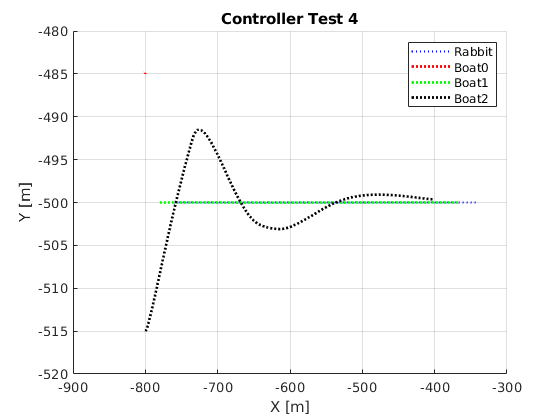

% Rabbit Position Data
rabbit_time = rabbitTs.Time;
rabbit_X = rabbitTs.Data(:,4);
rabbit_Y = rabbitTs.Data(:,5);


figure(1)
clf
grid on
hold on
plot(rabbit_X, rabbit_Y','b:','LineWidth',1.5)

% Boat Position Data
boat0_X = boat0Ts.Data(:,4);
boat0_Y = boat0Ts.Data(:,5);

boat1_X = boat1Ts.Data(:,4);
boat1_Y = boat1Ts.Data(:,5);

boat2_X = boat2Ts.Data(:,4);
boat2_Y = boat2Ts.Data(:,5);

plot(boat0_X,boat0_Y,'r:','LineWidth',2)
plot(boat1_X,boat1_Y,'g:','LineWidth',2)
plot(boat2_X,boat2_Y,'k:','LineWidth',2)
legend('Rabbit','Boat0','Boat1','Boat2','Location','best')
title('Controller Test 4')
xlabel('X [m]')
ylabel('Y [m]')

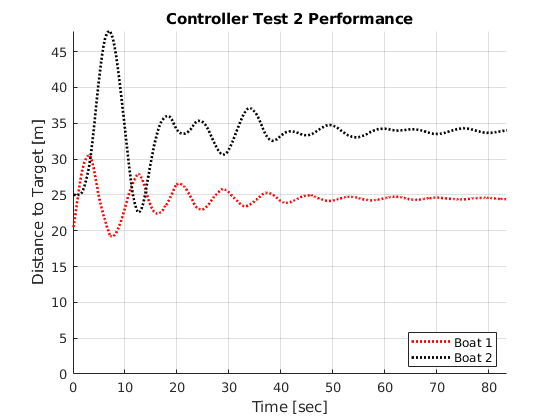

% Inter-vehicle spacing and distance to target

% Adjustments, if necessary
n0 = numel(boat0_X);
n1 = numel(boat1_X);
n2 = numel(boat2_X);
nr = numel(rabbit_X);
n = min([nr,n0,n1,n2]);
rabbit_time = rabbit_time((nr-n)+1:end);
% rabbit_time = rabbit_time - rabbit_time(1)
rabbit_X = rabbit_X((nr-n)+1:end);
rabbit_Y = rabbit_Y((nr-n)+1:end);
boat0_X = boat0_X((n0-n)+1:end);
boat0_Y = boat0_Y((n0-n)+1:end);
boat1_X = boat1_X((n1-n)+1:end);
boat1_Y = boat1_Y((n1-n)+1:end);
boat2_X = boat2_X((n2-n)+1:end);
boat2_Y = boat2_Y((n2-n)+1:end);

target0 = ((boat1_X - boat0_X).^2 + (boat1_Y - boat0_Y).^2).^0.5;
figure(2)
clf
% subplot(2,1,1)
grid on
hold on
title('Controller Test 2 Performance')
% plot(rabbit_time,target0,'b:','LineWidth',1.5)
ylabel('Distance to Target [m]')
xlabel('Time [sec]')

target1 = ((rabbit_X - boat1_X).^2 + (rabbit_Y - boat1_Y).^2).^0.5;
plot(rabbit_time,target1,'r:','LineWidth',2)


target2 = ((boat1_X - boat2_X).^2 + (boat1_Y - boat2_Y).^2).^0.5;
plot(rabbit_time,target2,'k:','LineWidth',2)
axis([0 rabbit_time(end) 0 max([max(target2),max(target1)])])
legend('Boat 1','Boat 2','Location','best')

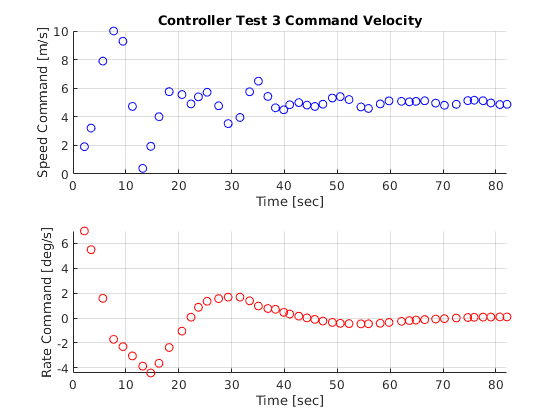


% subplot(2,1,2)
% grid on
% hold on
% spacing = ((boat0_X - boat2_X).^2 + (boat0_Y - boat2_Y).^2).^0.5;
% plot(rabbit_time,spacing,'g:','LineWidth',1.5)
% axis([0 rabbit_time(end) 0 50])
% ylabel('Spacing [m]')
% xlabel('Time [sec]')

figure(3)
clf
subplot(2,1,1)
grid on
hold on
plot(cmd2Ts.Time,cmd2Ts.Data(:,1),'bo','markersize',6)
xlabel('Time [sec]')
ylabel('Speed Command [m/s]')
xlim([0 cmd2Ts.Time(end)])
title('Controller Test 3 Command Velocity')

subplot(2,1,2)
grid on
hold on
plot(cmd2Ts.Time,rad2deg(cmd2Ts.Data(:,6)),'ro','MarkerSize',6)
xlabel('Time [sec]')
ylabel('Rate Command [deg/s]')
xlim([0 cmd2Ts.Time(end)])